# HW 11

Practice

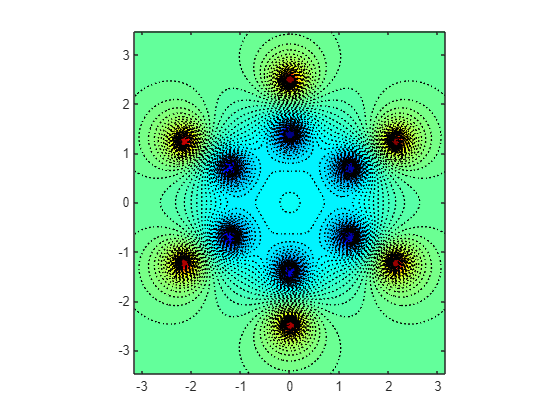

% Constants
eps0 = 8.8e-12;
k = 1 / (4 * pi * eps0);

% Read data from file
data = readtable('benzene.dat');
atoms = table2array(data(:, 2:4));
charge = table2array(data(:,5));

% Grid
x_min = min(atoms(:,1))-1;
x_max = max(atoms(:,1))+1;
y_min = min(atoms(:,2))-1;
y_max = max(atoms(:,2))+1;

g = linspace(x_min,x_max,100);
h = linspace(y_min,y_max,100);

[xg, yg] = meshgrid(g,h);
zg = zeros(size(xg));

% Potencial calculation
V = zeros(size(xg));
d = 0.1;
for i = 1:length(charge)
    xi = xg - atoms(i,1);
    yi = yg - atoms(i,2);
    zi = zg - atoms(i,3);
    r = sqrt(xi.^2 + yi.^2 +zi.^2);
    V = V + charge(i) * k ./ r;

    Vm = k * charge(i) / d;
    V(r < d) = Vm;
end

% 2D plot
figure;
contourf(xg,yg,V,100,':','LineWidth',1);
colormap(jet);
axis equal;

Homework - 3D

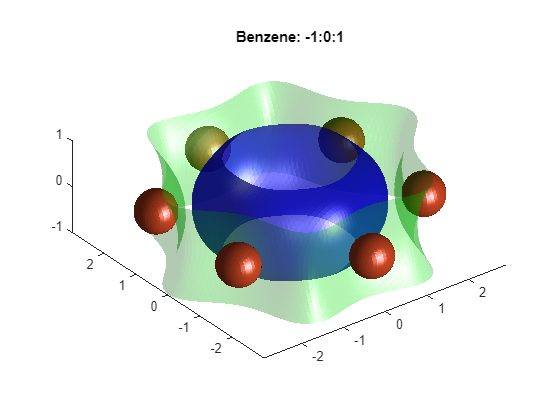

% Adaptation of the grid
z_min = min(atoms(:,3))-1;
z_max = max(atoms(:,3))+1;

f = linspace(z_min,z_max,100);

[xg, yg, zg] = meshgrid(h,g,f);

% Potencial calculation
V = zeros(size(xg));
d = 0.1;
for i = 1:length(charge)
    xi = xg - atoms(i,1);
    yi = yg - atoms(i,2);
    zi = zg - atoms(i,3);
    r = sqrt(xi.^2 + yi.^2 +zi.^2);
    V = V + charge(i) * k ./ r;

    Vm = k * charge(i) / d;
    V(r < d) = Vm;
end

% 3D plot
figure;

% Plot positive potential isosurfaces
isosurface(xg, yg, zg, V, max(V(:)) * 0.1); % 10% of max positive potential
colormap jet;
h1 = patch(isosurface(xg, yg, zg, V, max(V(:)) * 0.1));
set(h1, 'FaceColor', 'red', 'EdgeColor', 'none', 'FaceAlpha', 0.7);
% Plot negative potential isosurfaces
h2 = patch(isosurface(xg, yg, zg, V, min(V(:)) * 0.1));
set(h2, 'FaceColor', 'blue', 'EdgeColor', 'none', 'FaceAlpha', 0.7);
% Plot zero-level surface (green background)
h3 = patch(isosurface(xg, yg, zg, V, 0));
set(h3, 'FaceColor', 'green', 'EdgeColor', 'none', 'FaceAlpha', 0.3);

title('Benzene: -1:0:1');
axis equal;